b = 60;                    % Baseline in millimeters
f = 6;                     % Focal length in millimeters
ps = 0.006;                % Pixel size in millimeters
xNumPix = 752;             % Total Number of pixels in x direction of the sensor in pixels
shift = 10;                % Intrinsic displacement in pixels - closer object is greater the shift
cxLeft = xNumPix/2;        % Left camera x center in pixels
cxRight = xNumPix/2;       % Right camera x center in pixels
xLeft = (cxLeft + shift);   % left object x center in pixels
xRight = (cxRight - shift); % right object x center in pixels
disp(['xLeft is: ' num2str(xLeft) ' pixels'])

xLeft is: 386 pixels


disp(['xRight is: ' num2str(xRight) ' pixels'])

xRight is: 366 pixels


d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps)   % disparity in millimeters

d = 0.1200

disp(['Disparity is: ' num2str(d) ' millimeters'])

Disparity is: 0.12 millimeters


Z = (b*f)/d                                     % depth in millimeters

Z = 3000

disp(['Depth is: ' num2str(Z) ' millimeters'])

Depth is: 3000 millimeters


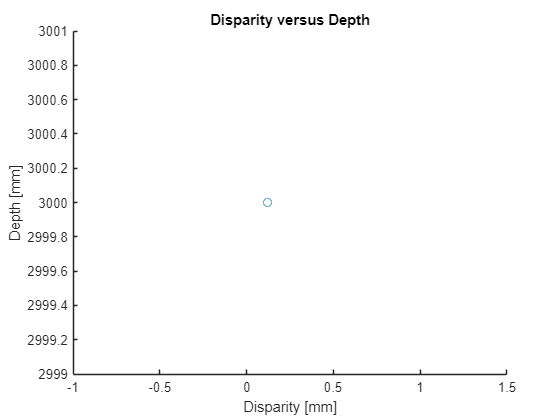

scatter(d,Z) % has to be scatter because plot needs more arguments
title('Disparity versus Depth')
xlabel('Disparity [mm]')
ylabel('Depth [mm]')